# Control and Instrumentation Lab Assignment 6

**SWARNENDU PAUL 19EE3FP18**

## Bode and Nyquist Plots

**Question 5.**

**a.**

$G(s)=\frac{K}{(s+8)(s+6)(s-2)}$ for $K=50,100,336,350$ 

Number of open loop poles in RHP, $P=1$

K=50

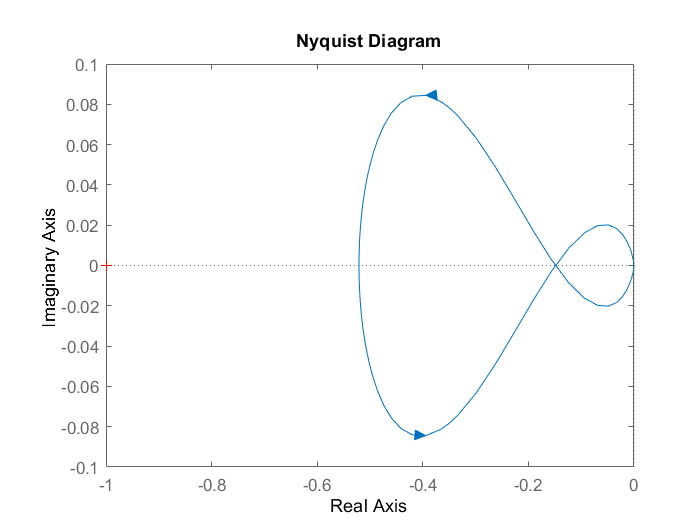

nyquist(zpk([],[-8,-6,2],50));

 The Nyquist plot doesn't encircle the point $-1+0j$ so $N=0$. Hence number of zeros of 1+G in RHP is N+P=1. Hence the closed-loop system is **unstable**.

K=100

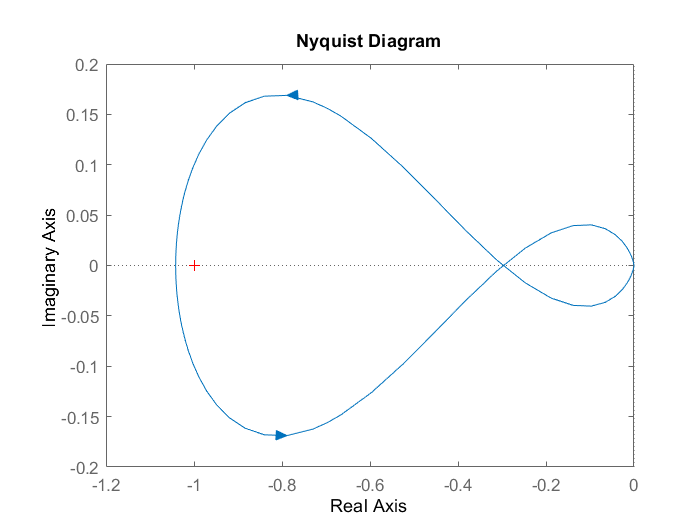

nyquist(zpk([],[-8,-6,2],100));

One CCW encirclement of $-1+0j$, hence $N=-1$. Number of zeros of 1+G in RHP is N+P=0. So, the closed-loop system is **stable**.

K=336

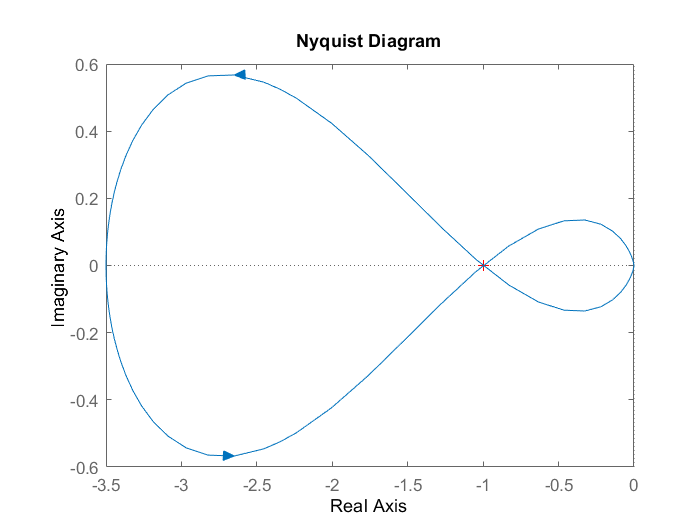

nyquist(zpk([],[-8,-6,2],336));

The nyquist plot passes through $-1+0j$, so the system has phase margin and gain margin(in dB) both equal to 0. Also the point is on a CCW loop of the nyquist plot so $N=-1$.Number of open loop zeros of 1+G in RHP is N+P=0. Closed-loop system is **marginally stable**.

K=350

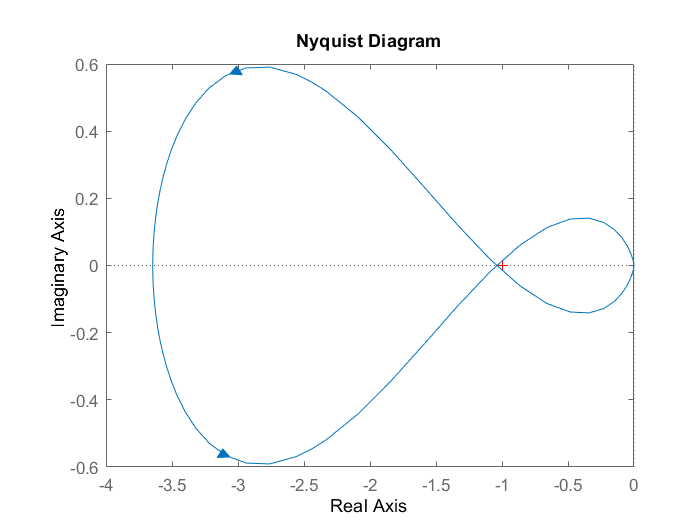

nyquist(zpk([],[-8,-6,2],350));

One CW encirclement of $-1+0j$, hence $N=1$. Number of zeros of 1+G in RHP is N+P=2. So, the closed-loop system is **unstable**.

**b.**

$G(s)=\frac{K}{s(s+3)(s+2)}$ for $K=20,30,100$

Number of open loop RHP poles, $P=0$

K=20

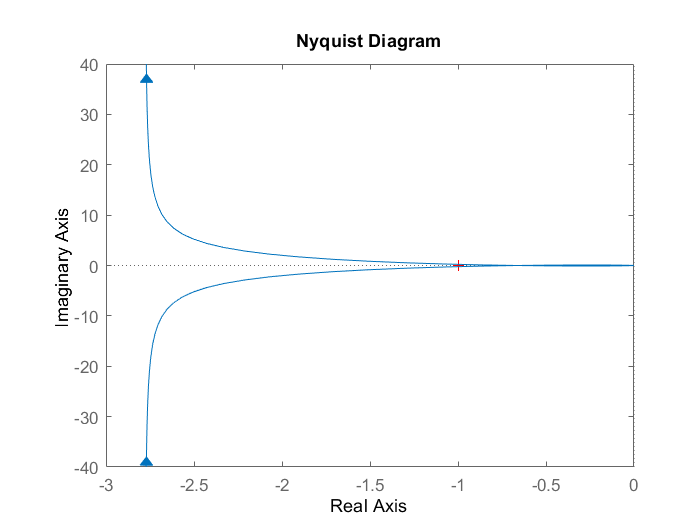

nyquist(zpk([],[0,-3,-2],20));

Number of poles in RHP of open-loop system: 0
Number of net encirclements around the -1 point:   0
=> Number of poles in RHP of closed-loop system:   0
and no closed-loop poles on Im-axis
=> Closed-loop-system is asymptotically stable


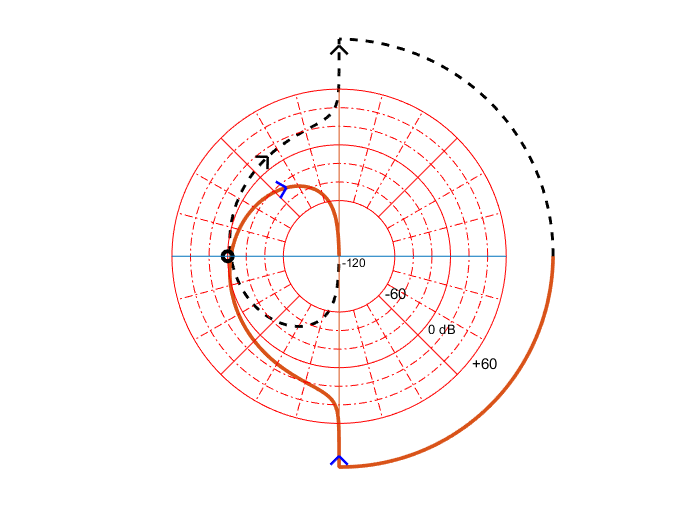

nyqlog(zpk([],[0,-3,-2],20));

As the system has open loop pole on imaginary axis, we used the user-built 'nyqlog' function to determine the complete nyquist diagram including it's behaviour at infinity. As we observe, nyquist plot doesn't encircle $-1+0j$, so $N=0$. Hence number of open loop zeros of 1+G in RHP is N+P=0. Closed-loop system is **stable**.

K=30

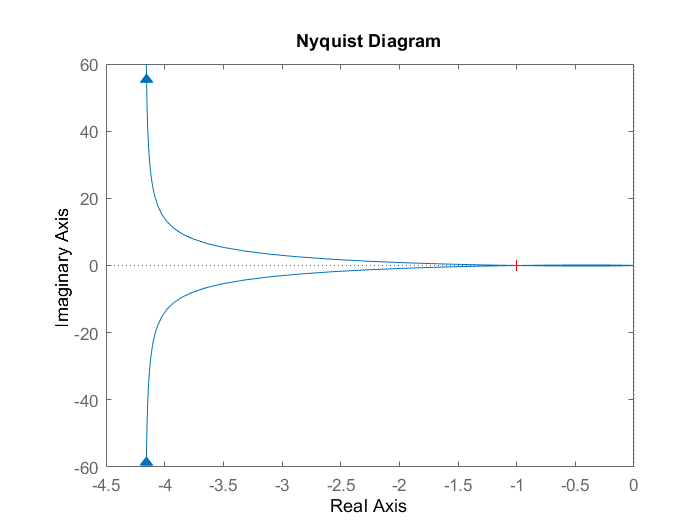

nyquist(zpk([],[0,-3,-2],30));

Number of poles in RHP of open-loop system: 0
Number of net encirclements around the -1 point:   0
=> Number of poles in RHP of closed-loop system:   0
and no closed-loop poles on Im-axis
=> Closed-loop-system is asymptotically stable


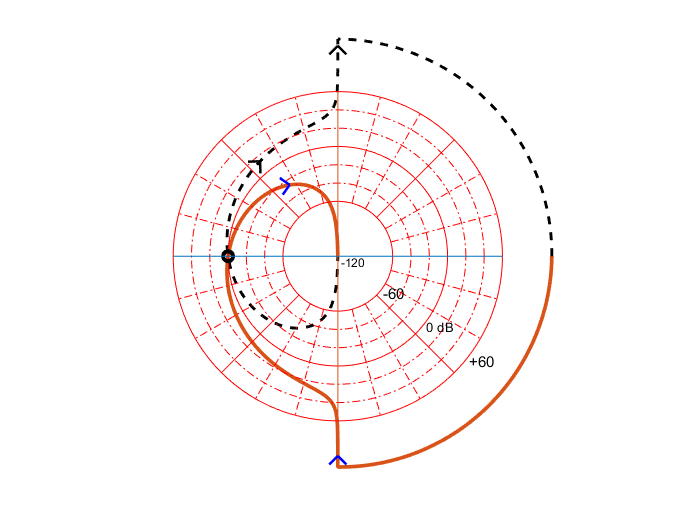

nyqlog(zpk([],[0,-3,-2],30));

 As we observe, nyquist plot passes through $-1+0j$, also it doesn't encircle the -1 point. So $N=0$. Number of open loop zeros of 1+G in RHP is N+P=0. But as the nyquist plot passes through -1 point, closed-loop system is **marginally stable**.

K=100

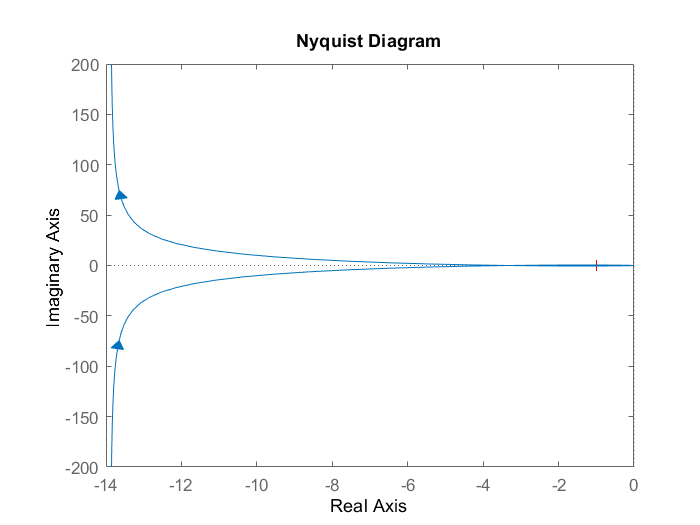

nyquist(zpk([],[0,-3,-2],100));

Number of poles in RHP of open-loop system: 0
Number of net encirclements around the -1 point:   2
=> Number of poles in RHP of closed-loop system:   2
=> Closed-loop-system is unstable


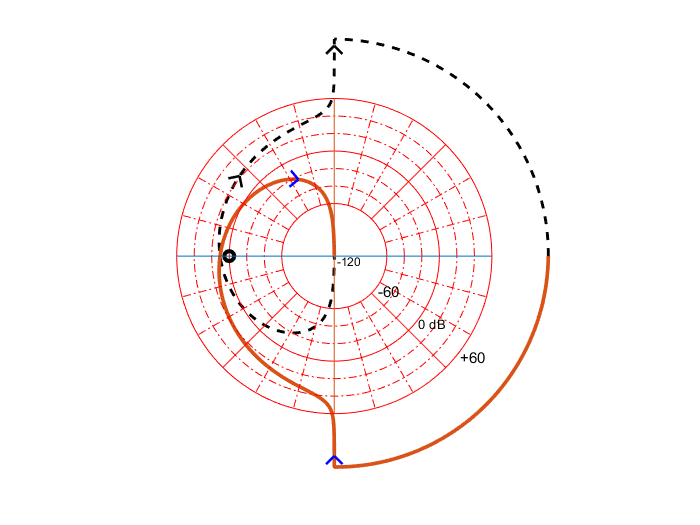

nyqlog(zpk([],[0,-3,-2],100));

2 CW encirclement of $-1+0j$, hence $N=2$. Number of zeros of 1+G in RHP is N+P=2. So, the closed-loop system is **unstable**. 

**c.**

$G(s)=\frac{K(s^2+10s+24)}{s^2-8s+15}$ ,for $K=0.5,0.8,1$

Number of open loop RHP poles, P=2

K=0.5

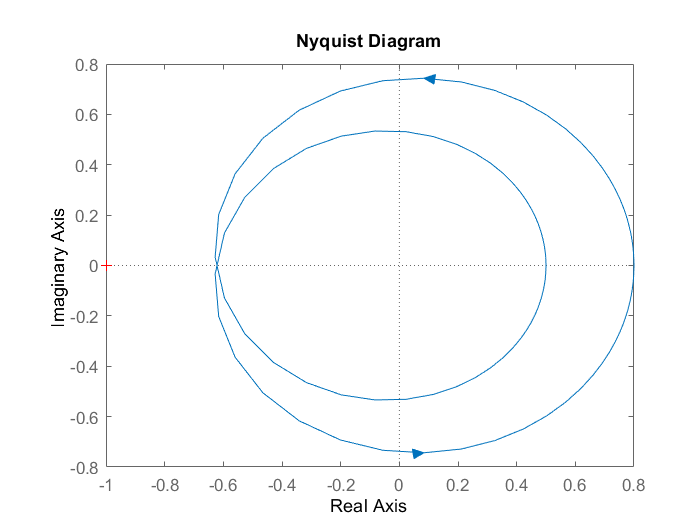

nyquist(tf([0.5,5,12],[1,-8,15]))

The nyquist plot doesn't encircle the -1 point, hence $N=0$. Number of zeros of 1+G in RHP is N+P=2. So, the closed-loop system is **unstable**.

K=0.8

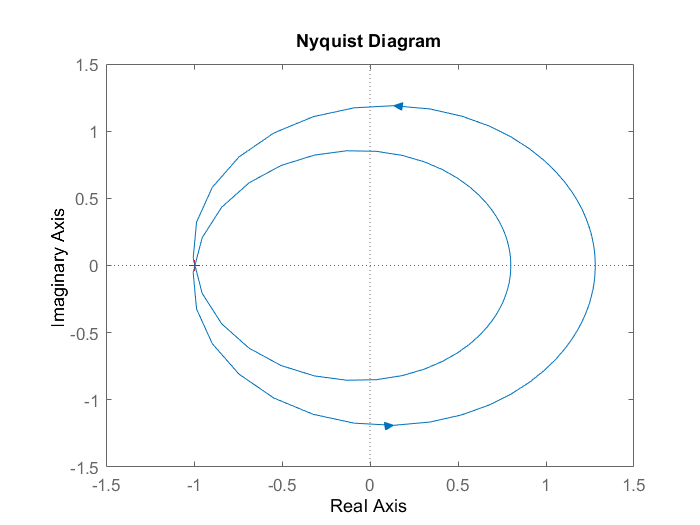

nyquist(tf([0.8,8,19.2],[1,-8,15]))

As we observe, nyquist plot passes through $-1+0j$, also the point is on 2 CCW loop of the nyquist plot, so $N=-2$. Number of open loop zeros of 1+G in RHP is N+P=0. But as the nyquist plot passes through -1 point, closed-loop system is **marginally stable**.

K=1

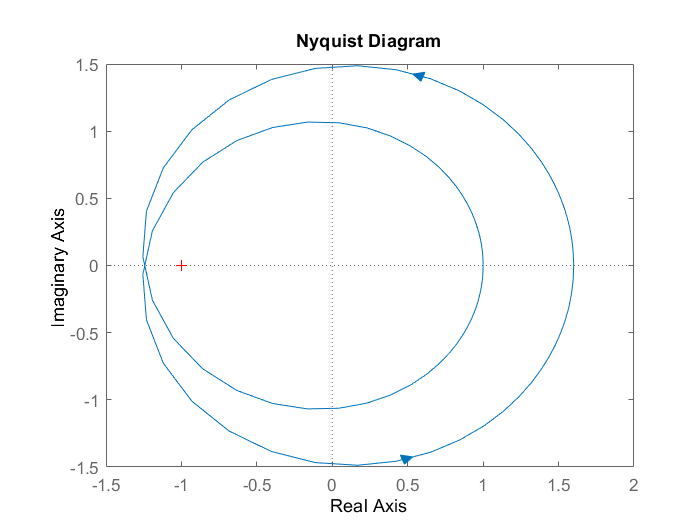

nyquist(tf([1,10,24],[1,-8,15]))

2 CCW encirclement of the -1 point, so $N=-2$. Number of open loop zeros of 1+G in RHP is N+P=0. Hence, the closed-loop system is **stable**. 

**d.**

$G(s)=\frac{10(s+p)}{s^2(s+3)}$ for $p=2,4$

Number of open loop poles in RHP, $P=0$.

p=2

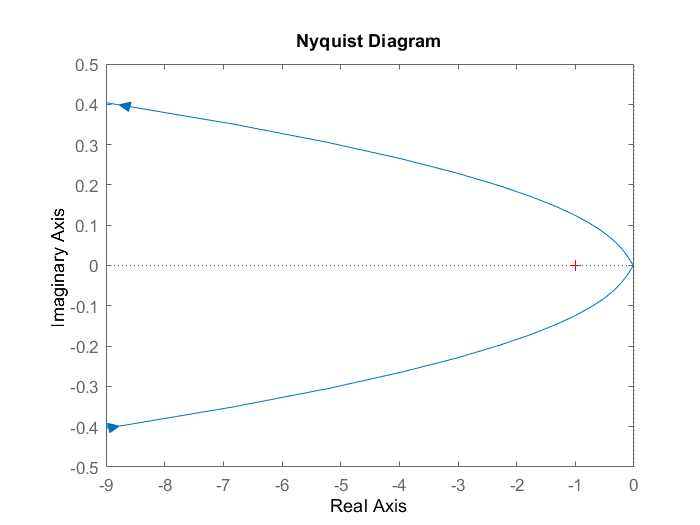

nyquist(zpk(-2,[0,0,-3],1))

Number of poles in RHP of open-loop system: 0
Number of net encirclements around the -1 point:   0
=> Number of poles in RHP of closed-loop system:   0
and no closed-loop poles on Im-axis
=> Closed-loop-system is asymptotically stable


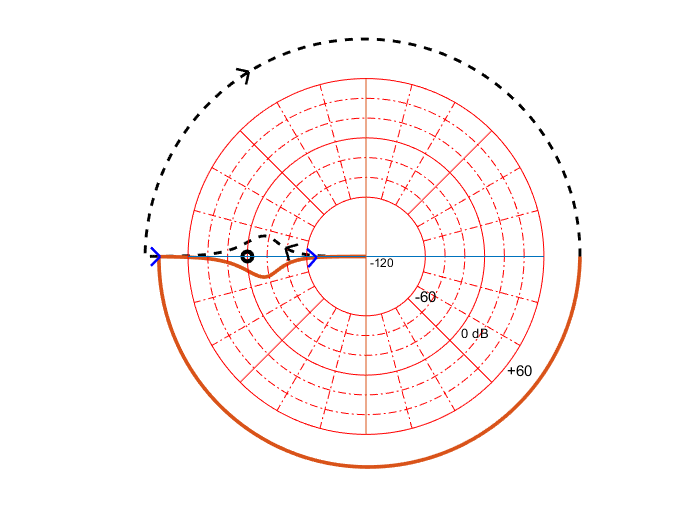

nyqlog(zpk(-2,[0,0,-3],1))

The nyquist plot doesn't encircle the -1 point, so $N=0$. Number of open loop zeros of 1+G in RHP is N+P=0. Hence, the closed-loop system is **stable**.

p=4

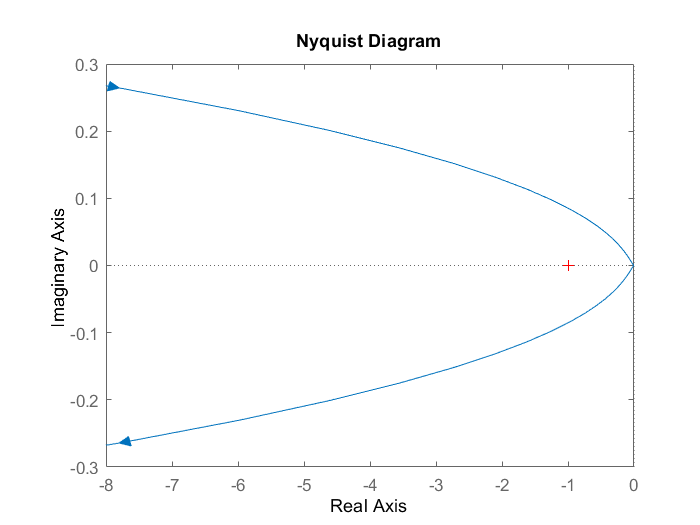

Number of poles in RHP of open-loop system: 0
Number of net encirclements around the -1 point:   2
=> Number of poles in RHP of closed-loop system:   2
=> Closed-loop-system is unstable


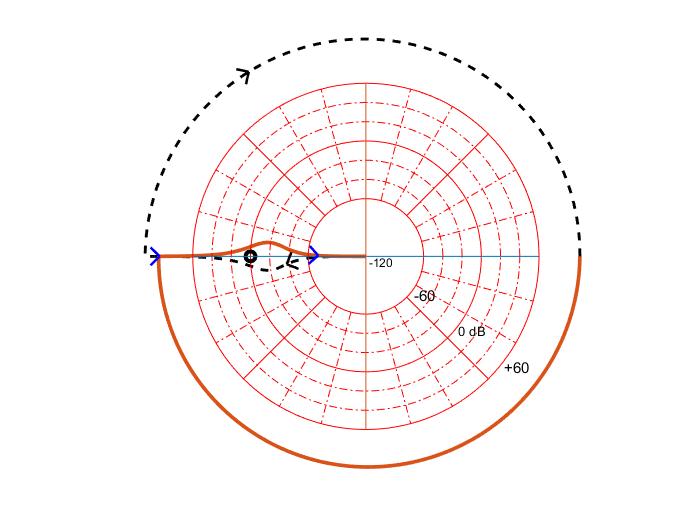

nyquist(zpk(-4,[0,0,-3],1))
nyqlog(zpk(-4,[0,0,-3],1))

2 CW encirclement of the -1 point, so $N=2$. Number of open loop zeros of 1+G in RHP is N+P=2. Hence, the closed-loop system is **unstable**.

**e.**

$G(s)= \frac{90}{(s+3)(s+6)}e^{-ps}$ for $p=0,0.05,0.5$

Number of open loop poles in RHP, $P=0$.

p=0

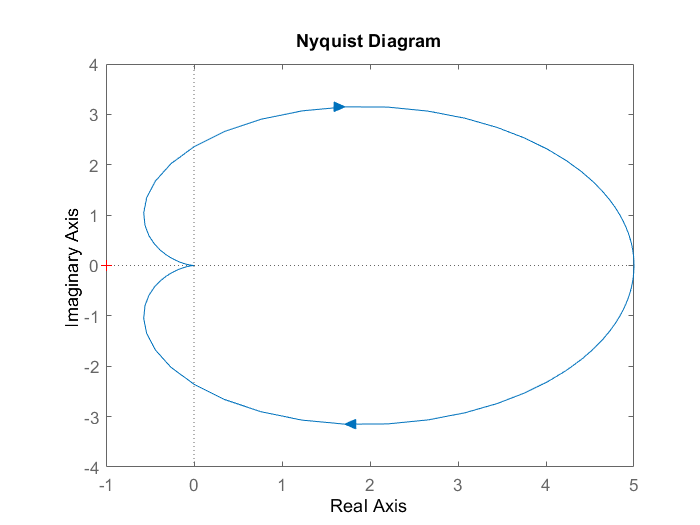

nyquist(tf(90,[1,9,18],'InputDelay',0))

The nyquist plot doesn't encircle the -1 point, so $N=0$. Number of open loop zeros of 1+G in RHP is N+P=0. Hence, the closed-loop system is **stable**.

p=0.05

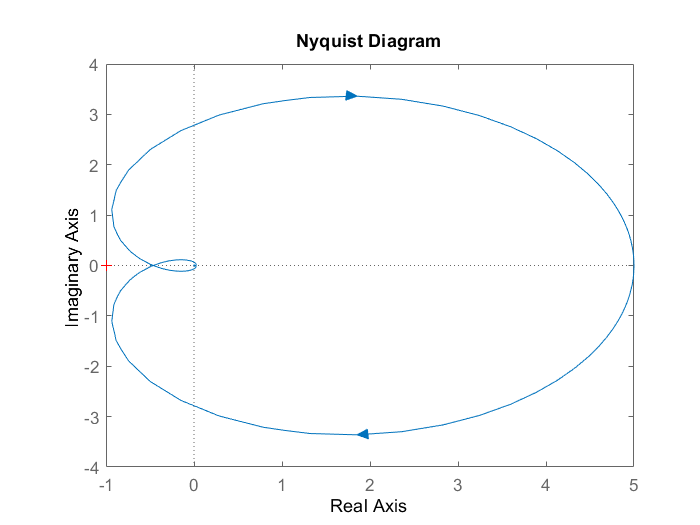

nyquist(tf(90,[1,9,18],'InputDelay',0.05))

The nyquist plot doesn't encircle the -1 point, so $N=0$. Number of open loop zeros of 1+G in RHP is N+P=0. Hence, the closed-loop system is **stable**.

p=0.5

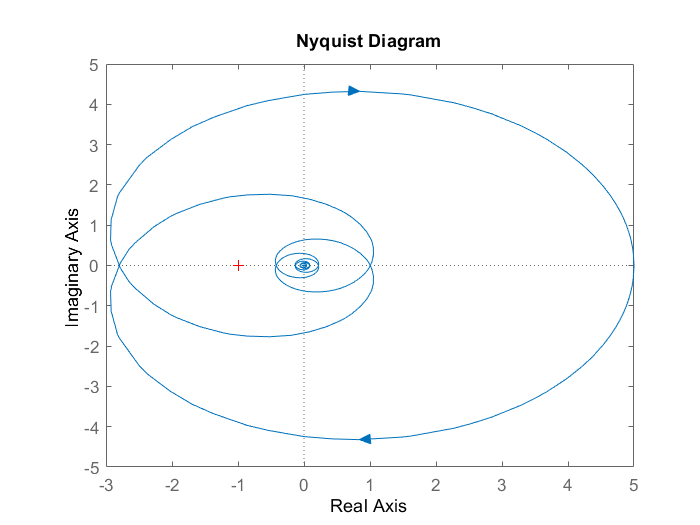

nyquist(tf(90,[1,9,18],'InputDelay',0.5))

2 CW encirclement of the -1 point, so $N=2$. Number of open loop zeros of 1+G in RHP is N+P=2. Hence, the closed-loop system is **unstable**.